# **Concentration Calculation**

Concentration Calculation calculates the concentration of the APT Dataset and visualises the data.

Before starting, you need a ranged pos file  or a decomposed pos file is possible

## Calculate the concentration, count and variance of each ion species

You can calculate the concentration using the detector Efficiency, an excludeList containing all elements which you don't want to contribute to the concentration. For example, you can exclude Ga ions that may be implemented during FIB preparation of your  If you want you can also name your volume.

detEff = 0.37; % detector efficiency of your Atom Probe (CAMECA LEAP 4000 XHR)
excludeList = {'Ga', 'unranged'}; % List of ions that don't contribute to the concentration calculation 
volumeName = 'volumeAll'; % name of the volume
conc = posCalculateConcentrationSimple(posdec, detEff, excludeList,volumeName) % calculates the count, concentration and variance

conc = 3×13 table
     volume      distance     type        format            H             C             N             O             Fe            F          Ga     unkownGaH      unranged 
    _________    ________    ______    _____________    __________    __________    __________    __________    __________    __________    ____    __________    __________

    volumeAll       0        atomic    count                  5952         15007          4364          2887    1.0641e+07           961    1965          2445    1.7064e+06
    volumeAll       

## Plot the concentration or count as a bar chart 

It is also possible to edit the exclude List and add more ions. ColorScheme is a variable input. If it is not parsed all bars appear in one color. You can also change the axis of the plot to a logarithmic scale.

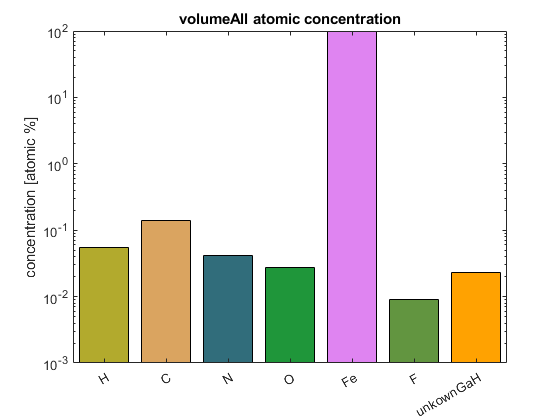

plotType = 'bar';
[p, ax, f] = concentrationPlot(conc([conc.format=='concentration'], :),excludeList, plotType, colorScheme);
ax.YScale = 'log'; % If you prefer a logarithmic scale

You can also plot your data based on count.

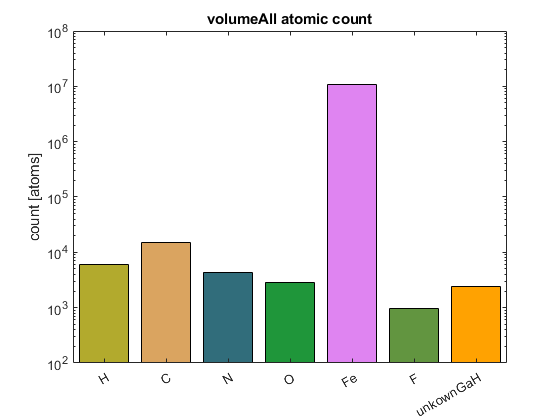

[p, ax, f] = concentrationPlot(conc([conc.format=='count'], :),excludeList, plotType, colorScheme);
ax.YScale = 'log';

## Plot the concentration or count as a pie chart

You can use the same syntax from above, just change the plotType.

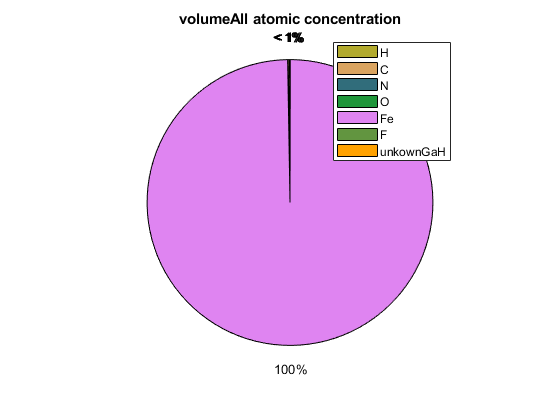

plotType = 'pie';
[p, ax, f] = concentrationPlot(conc([conc.format=='concentration'], :),excludeList, plotType, colorScheme); % concentration

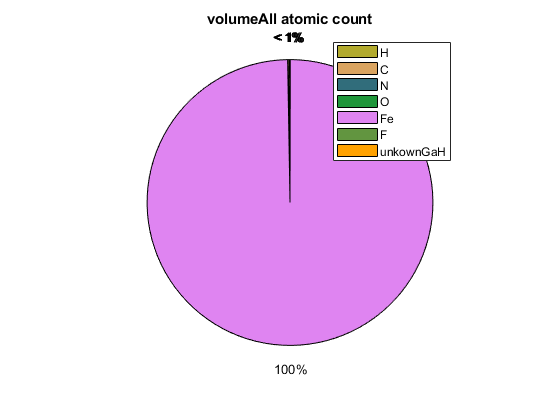

[p, ax, f] = concentrationPlot(conc([conc.format=='count'], :),excludeList, plotType, colorScheme); % counts

If one element is the main element of the composition you can add it to the exclude list to see the composition of the residual ions

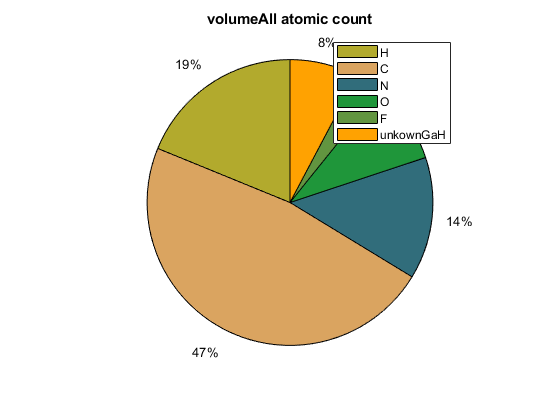

excludeList = {'Ga', 'unranged', 'Fe'};
[p, ax, f] = concentrationPlot(conc([conc.format=='count'], :),excludeList, plotType, colorScheme);